clc;
clear;
close all;

## Esercizio 1

generi in modo pseudo-random un numero n intero tra 1 e 40 e verifichi che sia divisibile per 4. Stabilito che il numero inserito soddisfa i requisiti richiesti, si costruisca e si visualizzi la matrice D di dimensione n × n fatta nel seguente modo:

dove, assegnato a m il valore $\frac{n}{4}$ ,

• D1 ∈ $R^{m\times m}$ contiene tutti valori uguali a −1;

• D2 ∈ $R^{m\times m}$ contiene tutti valori uguali a −2;

• D3 ∈ $R^{m\times m}$ contiene tutti valori uguali a −3;

• D4 ∈ $R^{m\times m}$ contiene tutti valori uguali a −4.

Si construiscano e si visualizzino, inoltre, il vettore z con tutti elementi uguali a 3 e il vettore y = D · z.

Se il numero generato n non dovesse verificare le condizioni richieste, dovrà esserne richiesto uno nuovo fino a quando non si ottiene un numero consentito.

n = 4 * randi([1 10], 1);

m = n/2;

D1 = -1 * ones(m);
D2 = -2 * ones(m);
D3 = -3 * ones(m);
D4 = -4 * ones(m);

D = [D1 D2; D3 D4]

D =     -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2
    -3    -3    -3    -3    -3    -3    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -4    -4    -4    -4    -4    -4
    -3    -3    -3    -3    -3    -3    -4    -4    -4    -4    -4    -4



z = 3 * ones(n, 1);

y = D * z

y =    -54
   -54
   -54
   -54
   -54
   -54
  -126
  -126
  -126
  -126
  -126
  -126


clc;
clear;
close all;

## Esercizio 2

crei la matrice dei coefficienti di un sistema lineare Ax = b, con A ∈ R20×20, contenente numeri pseudo-casuali reali compresi tra −2 e 2. Sostituire la sua diagonale con elementi tutti uguali a 100. Successivamente, imporre una soluzione nota x di elementi uguali a −2 e calcolare il corrispondente termine noto b e trovare l’approssimazione x1 della soluzione del sistema utilizzando il metodo iterativo di Gauss-Seidel. Impostare una tolleranza τ = 10e−5 e un numero massimo di iterazioni kmax = 100. Infine, calcoli e visualizzi l’errore relativo tra la soluzione vera x e quella ottenuta x1 .

iMin = -2;
iMax = 2;
n = 20;
tau = 10e-5;
kmax = 100;

A = (iMax-iMin) * rand(n) + iMin;
for i = 1:n
    A(i, i) = 100;
end

x = -2 * ones(n, 1);

b = A * x;

[x1, k] = gauss_seidel(A, b, x0, tau, k_max);

errRel = norm(x - x1) / norm(x);

clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

utilizzando il metodo di Newton, con punto iniziale x0 = 1, e con il metodo di bisezione, partendo dall’intervallo [0, 4]. Per entrambi i metodi, impostare una tolleranza τ = 10e−5 e un numero massimo di iterazioni kmax = 100. Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e le due approssimazioni ottenute. Il grafico dovrà essere corredato da un titolo e una legenda.

Le due funzioni

• [xn, kn] = newton(f, fder, x0, τ, kmax)

• [xb, kb] = bisezione(f, a, b, τ, kmax)

dovranno essere allegate alla fine dello script.

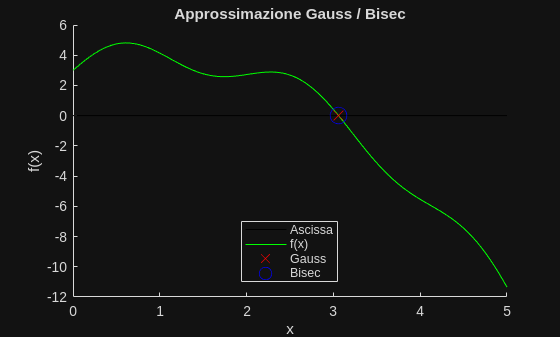

tau = 10e-5;
x0 = 1;
kmax = 100;
a = 0;
b = 4;

f = @(x) sin(3.*x) - x.^2 + 2.*x + 3;
fder = @(x) 3.*cos(3.*x) - 2.*x + 2;

[xn, kn] = newton(f, fder, x0, tau, kmax);
[xb, kb] = bisezione(f, a, b, tau, kmax);

figure;
hold on;

title("Approssimazione Gauss / Bisec");
xlabel("x");
ylabel("f(x)");

x = linspace(0, 5, 100);

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "xr", "DisplayName", "Gauss", "MarkerSize", 10);
plot(xb, f(xb), "ob", "DisplayName", "Bisec", "MarkerSize", 12);

legend("Location", "best");

hold off;

function [x, k] = gauss_seidel(A, b, x0, tau, k_max)

    % gauss_seidel: metodo per trovare un'approssimazione delle radici 
    % tramite iterazioni successive di un sistema di equazioni lineari
    %   [x, k] = gauss_seidel(A, b, x0, tau, k_max) restituisce le 
    % soluzioni della matrice e il numero di iterazioni effettuate.

    % tau e k_max sono le condizioni d'arresto:
        % tau = tolleranza
        % k_max = iterazioni massime
    
    % Controllo del numero di parametri in input
    if (nargin > 5)
        error("Sono stati inseriti troppi parametri in input");
    end
    
    % Controllo che la matrice non sia singolare
    if (abs(det(A)) < 1e-12)
        error("Il sistema può non ammettere soluzioni");
    end
    
    % Nel caso la funzione gauss_seidel venga chiamata con meno parametri, 
    % allora imposto manualmente i parametri mancanti
    if (nargin < 5)
        k_max = 1000;
    end
    if (nargin < 4)
        tau = 1e-14;
    end
    if (nargin < 3)
        x0 = zeros(size(A, 1), 1);
        x0(1) = 1;
    end
    
    % A = D - E - F
    
    % diag() restituisce un vettore, quindi diag() su di esso mi rende una 
    % matrice con tutti 0 tranne la diagonale, che avrà i valori del
    % vettore
    D = diag(diag(A));
    
    %E = (tril(A) - D) * -1;
    E = -tril(A, -1);
    
    F = -triu(A, 1);
    
    %Bgs = (D - E)^-1 * F;
    Bgs = (D - E) \ F;
    
    %fgs = (D - E)^-1 * b;
    fgs = (D - E) \ b;
    
    % Un MLS1 converge quando il rho della matrice di iterazione è < 1
    rho = abs(eigs(Bgs, 1, 'largestabs')); % anche con largestabs restituisce l'autovalore col suo segno originario
    
    if (rho >= 1)
        error("Il metodo non converge");
    end
    

    % Inizializzazione variabili
    x_old = x0;
    flag = true;
    k = 1;


    while (flag)

        % Condizione di stop per massimo numero di iterazioni
        if (k >= k_max)
            warning("k_max è stato raggiunto");
            break;
        end
    
        % Passo iterativo Gauss-Seidel
        x_new = Bgs * x_old + fgs;
    
        % Condizione di stop per soluzioni accettabili, cioè abbastanza
        % vicine alla soluzione reale
        if (norm(x_new - x_old) < tau * norm(x_new))
            flag = false;
        else
            % Aggiornamento variabili per l'iterazione successiva
            x_old = x_new;
            k = k + 1;
        end
    end
    
    x = x_new;
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)
    kn = 1;
    xn = -1;
    f1 = fder(x0);

    if(abs(f(x0)) < tau)
        xn = x0;
        return;
    end

    while(kn < kmax && abs(f(xn)) >= tau)
        
        if(abs(f1) < tau)
            error("Cambia x0");
        end

        xn = x0 - f(x0) / f1;
        
        x0 = xn;
        f1 = fder(x0);

        kn = kn + 1;
    end
end

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    kb = 1;
    xb = -1;
    fxb = -1;

    fa = f(a);
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [" + a, + ", " + b + "]");
    end

    while(kb < kmax && abs(fxb) >= tau)
       
        xb = (a + b) / 2;
        
        fxb = f(xb);
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end


        kb = kb + 1;
    end
end